# INF250 - CA5 - Deadline xxx

### Upload your CA5_<your_mitt_id> zipped folder submission on Mitt, including all the files (2 .mlx files and one .csv file). Make sure you submitted the correct files, and that they all work on an external machine.

During the fifth and final round of the programming assignments, we will focus on visualization. This time, instead of filling out parts of already written code, you will start with a blank project *( CA5_<your_mitt_id> ) *and write everything yourself*.* In the end, deliver your finished project, containing the following parts:

## Part 1: What (20%)

*In this part we are going to present what we are going to visualize in this presentation.*

I chose this data set [https://www.ssb.no/statbank/table/05869/tableViewLayout1/](https://www.ssb.no/statbank/table/05869/tableViewLayout1/) 

I chose this data set because i want to explore how different years have effected migration, i can imagine world events like pandemics, wars and financial crisises would affect the migration data, so to figure this out i want to visualize this data set and also see if there is any major differences between men and women.

I chose my dataset to be amount of people moving to and from norway per year. between 1958 and 2022. I have 6 attributes:

1: Total number of people moving in to the country

2: Total number of Men moving in to the country

3: Total number of Woman moving in to the country

4: Total number of people moving out of the country

5: Total number of Men moving out of the country

6: Total number of Woman moving out of the country

The data set is both categorical and quantitative, categorical is the attributes mentioned above and the quantitative is the number of people. They do not have any ordering direction except for year. This means that i have temporal infor in the form of years. And i have spatial info in the sense that this data is based on moving in and out of Norway.

**Expectations and hypothesis**

I expect to see some differences in migration patterns between men and woman due to some external factors like, work, family or personal reasons.

Some hypotheses i have about the data would be that is expect the migration to grow bigger the closer the year is to the current year, due to growth in both population and globalisation. I also expect the migration numbers to be very low during the COVID pandemic from 2020-2022. Due to a lot of borders being closed to prevent the spread of the virus.

**Target audience**

My target audience for this visualization could be researchers that are intrested in understanding population migration. Or it could be used by politicians to help drive discussion aroiund Norways migration policy.

#### **MY IMPORTED DATA**

%% Set up the Import Options and import the data
opts = spreadsheetImportOptions("NumVariables", 7);

% Specify sheet and range
opts.Sheet = "InnflytTot";
opts.DataRange = "A4:G68";

% Specify column names and types
opts.VariableNames = ["VarName1", "InnflyttingerIAlt", "InnflyttingerMenn", "InnflyttingerKvinner", "UtflyttingerIAlt", "UtflyttingerMenn", "UtflyttingerKvinner"];
opts.VariableTypes = ["categorical", "double", "double", "double", "double", "double", "double"];

% Specify variable properties
opts = setvaropts(opts, "VarName1", "EmptyFieldRule", "auto");

% Import the data
flyttingetetterrogkjnn_V1 = readtable("flyttinget etter år og kjønn_V1.xlsx", opts, "UseExcel", false);


%% Clear temporary variables
clear opts

## Part 2: Why (20%)

*In this part, the focus is why to visualize this data*

**Data exploration**

After exploring the data we can find trends in migration patterns, differences between in and out migration based on sex and we can identify periods of growth or decline in migration. Now if we imagine a researcher that wants to example figure out why there are so many women compared to men in a country then we could present the data in a form that compares migration between genders. If the user finds that there is a lot of in-migration of women and out-migration of men, then the visualization helped the researcher to figure out a possible anwser of their question. The action target pair in this context would be:

Action: Investigate gender diferences in migration over a time period

Target: The data cointaining the information, of in-migration and out-migration based on gender. And not the total migration.

**Form**

The best way to visualize this data would then be to do comparative visualizations, since we have atributes that are easily comparable like men and women and in and out migration. Some visualizations include stacked bar charts, grouped barcharts or even stacked area charts. Line charts can also help us to compare by visualizing more than one line in the plot. We can help the user to find their target location and what they search for by visualizing the entire data set and then pick out certain anomalies in the data, like sudden spikes, or drops, big difference in out and in-migraton or big difference in amount of migrating men and migrating women. However the user might have some hypotesis like for example that In-migration spiked after norway found oil in 1969, due to Norway importing workers. Then we could visualize some years before 1969 and then after 1969 to see if this is actualy true. Now both the location and target is known ans the user can just lookup the anwser.

## Part 3: How (50%)

*Here we wil present how to visualize the data, we will show some visualizations and then explore our findings*

**FIGURE 1-3**

We can see from our findings that in-migrations are generaly more common than outmigrations, we can see this in figure 1 as the blue column is biggerer than the red column. However we can see that the inflows has gradualy increased over the years until about 2010 before it dips again. And then spikes in 2022.

So if we cointinue to explore the next two figures, figure 2 and figure 3 we can see that  there is more men that inflows and outflows after the 2000s. However this changed suddenly in 2022, where the in-migrations of women spiked above inflow of men, this is something that could be explored further in figure 12.

**FIGURE 4-6**

It seems a bit hard to compare inflows and outflows with grouped barcharts when we have this many data points so in figure 4, 5 and 6 we visualize this with line graphs.

If we look at figure 4 we can see that from 1958 to 1970 it is pretty close between in and out flows, after this inflows becomes bigger, except in 1989 where there was more outflows compared to inflows. This can then help us to ask a quesion, what happened in 1989? Seeing as this was the year that the berlin wall fell we can argue that there is a connection, because there might have been germans living in norway that migrated back to east germany after the fall of the berlin wall.

If we look at figure 5 we can see that there is most men that migrate in to norway except some periods like i 1993 and 2004 and in the year 2022. We can assume this is refugees, and since there is often men that are soliders, it would make sense that more women seek refuge than men.

While if we look at fig 6 we can see that the gender that the sex that migrates out the most historicaly has been men except between 1958-1973 where it was most women that migrated out of the country

**FIGURE 7-9**

Now if we want to compare it even further we can use a comparative visualization like stacked bar charts. This is what i have done in figure 7, 8 and 9. This visualization is especially usefull to see the difference. Like in figure 7 we can see in 2022 that there are much more women compared to men that migrate in to the country.

And we can also see in figure 9 that in 2022 there was much more inflows than outflows. If we compare we can see thet there is about 3 times more inflows than outflows in 2022.

**FIGURE 10-12**

Now for figure 10, 11 and 12 we have chosen some years to further investigate how the different values for that year compare. The years i have chosen are years where the data does not follow the normal trend.

The years i chose were 1989, 2022 and 2020. The entire pie chart represent the entire migration for that year for both inflow and outflow. So if we look at figure 10 we can see that the 4 different slices of the piechart is relatively equal, except that maybe there are more men that migrates out from the country in 1989.

In figure 2020 we can see that the 4 slices are more unevenly distributed, we see that there is more migrations in to the country compared to out.

And lastly if we lok at 2022 we can see the least evenly distributed slices in the pie chart, we can see that 3/4 of the migration is In to the country while 1/4 is migration out of the country. Now we can also see that there seems to be more women than men that migrate to the country, but that there is not that much of a difference that it first seemed in the stacked bar chart. In this same figure we can also see that there is more out-migrations of men than women.

**Hypothesis**

Now if we want to test the hypothesis that was mentioned in the why section: In-migration spiked after norway found oil in 1969, due to Norway importing workers. We can look at figure 4 and look at the blue line. We can se a slight increase in inflow after 1969, but it actualy goes a bit down after 1971. And if we look at fiugre 7 and look at the blue bars in the stacked bar chart, we can see easily that there realy is not a big spike in inflows after 1969, so we can conclude thath this hypothesis is not correct.

### *CODE*

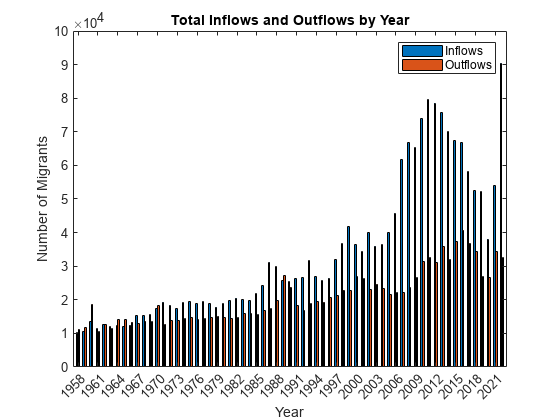

% Bar chart for total inflows and outflows
figure;
bar(categorical(flyttingetetterrogkjnn_V1.VarName1), [flyttingetetterrogkjnn_V1.InnflyttingerIAlt, flyttingetetterrogkjnn_V1.UtflyttingerIAlt]);
title('Total Inflows and Outflows by Year');
xlabel('Year');
ylabel('Number of Migrants');
legend({'Inflows', 'Outflows'});
% x-axis show every 3 years
years_to_display = arrayfun(@num2str, 1958:3:2022, 'UniformOutput', false);
xticks(years_to_display);
xticklabels(years_to_display);

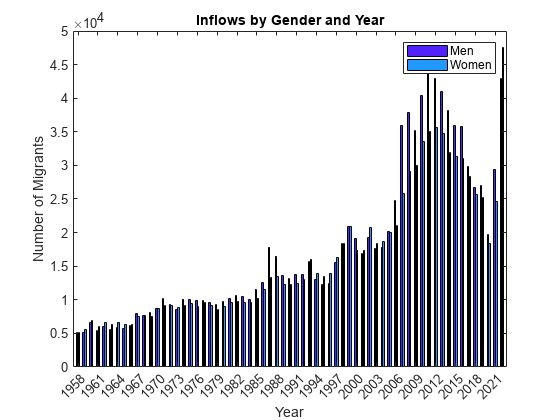




% Bar chart for inflows by gender
figure;
bi = bar(categorical(flyttingetetterrogkjnn_V1.VarName1), [flyttingetetterrogkjnn_V1.InnflyttingerMenn, flyttingetetterrogkjnn_V1.InnflyttingerKvinner]);
bi(1).FaceColor = [0.32 0.13 1];
bi(2).FaceColor = [0.13 0.6 1];
title('Inflows by Gender and Year');
xlabel('Year');
ylabel('Number of Migrants');
legend({'Men', 'Women'});
% x-axis show every 3 years
years_to_display = arrayfun(@num2str, 1958:3:2022, 'UniformOutput', false);
xticks(years_to_display);
xticklabels(years_to_display);

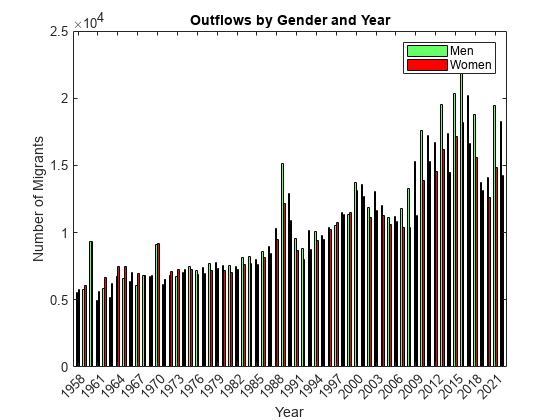



% Bar chart for outflows by gender
figure;
bo = bar(categorical(flyttingetetterrogkjnn_V1.VarName1), [flyttingetetterrogkjnn_V1.UtflyttingerMenn, flyttingetetterrogkjnn_V1.UtflyttingerKvinner]);
bo(1).FaceColor = [0.4 1 0.4];
bo(2).FaceColor = [1 0 0];
title('Outflows by Gender and Year');
xlabel('Year');
ylabel('Number of Migrants');
legend({'Men', 'Women'});
% x-axis show every 3 years
years_to_display = arrayfun(@num2str, 1958:3:2022, 'UniformOutput', false);
xticks(years_to_display);
xticklabels(years_to_display);

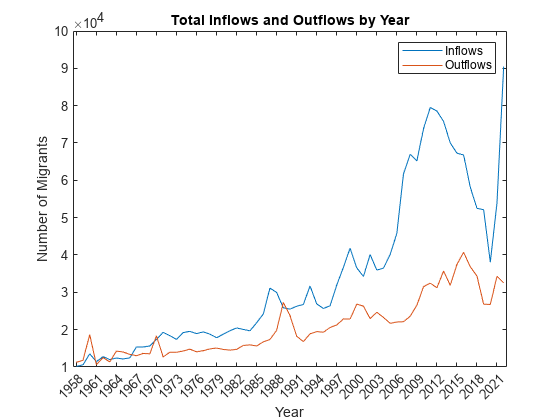



% Line plot for total inflows and outflows
figure;
plot(categorical(flyttingetetterrogkjnn_V1.VarName1), [flyttingetetterrogkjnn_V1.InnflyttingerIAlt, flyttingetetterrogkjnn_V1.UtflyttingerIAlt]);
title('Total Inflows and Outflows by Year');
xlabel('Year');
ylabel('Number of Migrants');
legend({'Inflows', 'Outflows'});
% x-axis show every 3 years
years_to_display = arrayfun(@num2str, 1958:3:2022, 'UniformOutput', false);
xticks(years_to_display);
xticklabels(years_to_display);

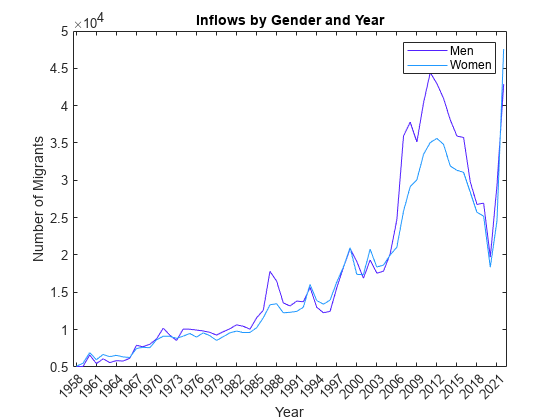


% Line plot for inflows by gender
figure;
li = plot(categorical(flyttingetetterrogkjnn_V1.VarName1), [flyttingetetterrogkjnn_V1.InnflyttingerMenn, flyttingetetterrogkjnn_V1.InnflyttingerKvinner]);
li(1).Color = [0.32 0.13 1];
li(2).Color = [0.13 0.6 1];

title('Inflows by Gender and Year');
xlabel('Year');
ylabel('Number of Migrants');
legend({'Men', 'Women'});
% x-axis show every 3 years
years_to_display = arrayfun(@num2str, 1958:3:2022, 'UniformOutput', false);
xticks(years_to_display);
xticklabels(years_to_display);

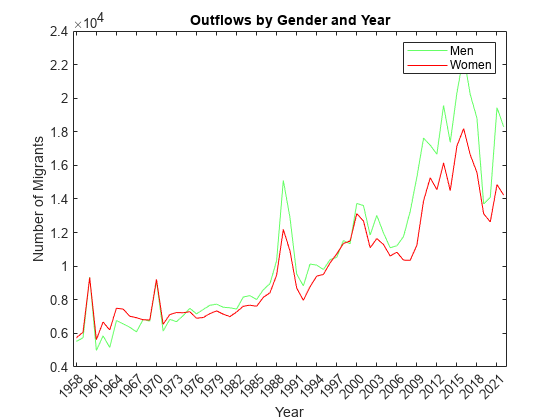


% Line plot for outflows by gender
figure;
lo = plot(categorical(flyttingetetterrogkjnn_V1.VarName1), [flyttingetetterrogkjnn_V1.UtflyttingerMenn, flyttingetetterrogkjnn_V1.UtflyttingerKvinner]);

lo(1).Color = [0.4 1 0.4];
lo(2).Color = [1 0 0];

title('Outflows by Gender and Year');
xlabel('Year');
ylabel('Number of Migrants');
legend({'Men', 'Women'});
% x-axis show every 3 years
years_to_display = arrayfun(@num2str, 1958:3:2022, 'UniformOutput', false);
xticks(years_to_display);
xticklabels(years_to_display);

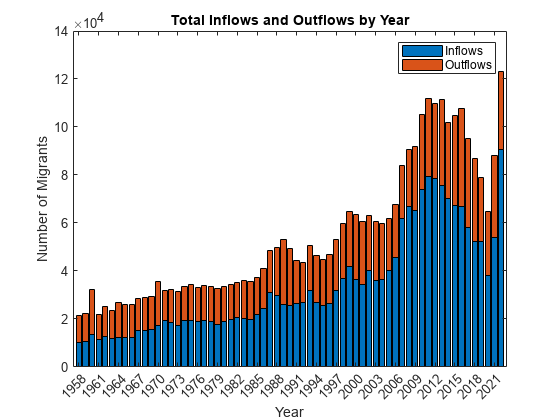


% Stacked bar chart for inflows and outflows by gender
figure;
bar(categorical(flyttingetetterrogkjnn_V1.VarName1), [flyttingetetterrogkjnn_V1.InnflyttingerMenn + flyttingetetterrogkjnn_V1.InnflyttingerKvinner, flyttingetetterrogkjnn_V1.UtflyttingerMenn + flyttingetetterrogkjnn_V1.UtflyttingerKvinner], 'stacked');
title('Total Inflows and Outflows by Year');
xlabel('Year');
ylabel('Number of Migrants');
legend({'Inflows', 'Outflows'});
% x-axis show every 3 years
years_to_display = arrayfun(@num2str, 1958:3:2022, 'UniformOutput', false);
xticks(years_to_display);
xticklabels(years_to_display);

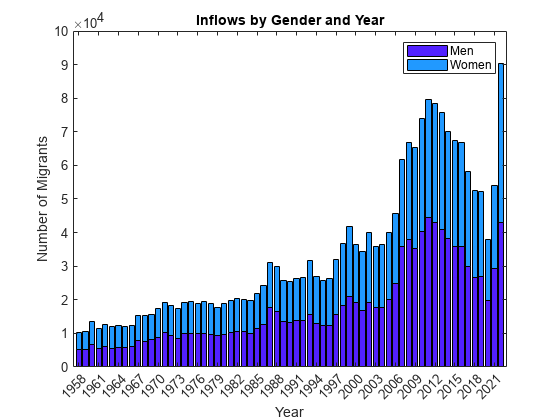



% Stacked bar chart for inflows by gender
figure;
sbi = bar(categorical(flyttingetetterrogkjnn_V1.VarName1), [flyttingetetterrogkjnn_V1.InnflyttingerMenn, flyttingetetterrogkjnn_V1.InnflyttingerKvinner], 'stacked');
title('Inflows by Gender and Year');
xlabel('Year');
ylabel('Number of Migrants');
legend({'Men', 'Women'});

sbi(1).FaceColor = [0.32 0.13 1];
sbi(2).FaceColor = [0.13 0.6 1];

% x-axis show every 3 years
years_to_display = arrayfun(@num2str, 1958:3:2022, 'UniformOutput', false);
xticks(years_to_display);
xticklabels(years_to_display);

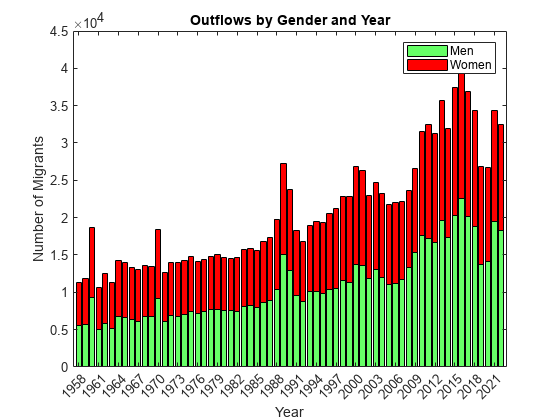


% Stacked bar chart for outflows by gender
figure;
sbo = bar(categorical(flyttingetetterrogkjnn_V1.VarName1), [flyttingetetterrogkjnn_V1.UtflyttingerMenn, flyttingetetterrogkjnn_V1.UtflyttingerKvinner], 'stacked');
title('Outflows by Gender and Year');
xlabel('Year');
ylabel('Number of Migrants');
legend({'Men', 'Women'});

sbo(1).FaceColor = [0.4 1 0.4];
sbo(2).FaceColor = [1 0 0];

% Specify the years to display on the x-axis
years_to_display = arrayfun(@num2str, 1958:3:2022, 'UniformOutput', false);
xticks(years_to_display);
xticklabels(years_to_display);

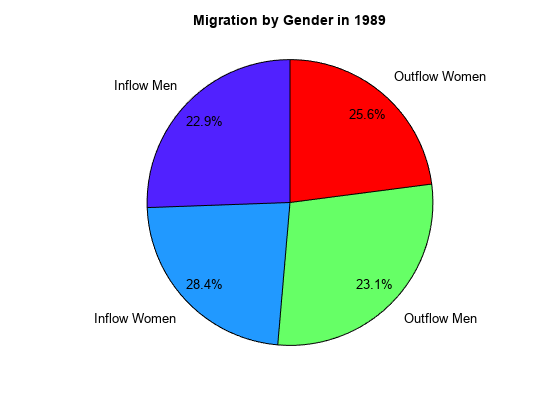




figure;
year = 1989;
data = [flyttingetetterrogkjnn_V1.InnflyttingerMenn(find(flyttingetetterrogkjnn_V1.VarName1 == string(year))), flyttingetetterrogkjnn_V1.InnflyttingerKvinner(find(flyttingetetterrogkjnn_V1.VarName1 == string(year))), flyttingetetterrogkjnn_V1.UtflyttingerMenn(find(flyttingetetterrogkjnn_V1.VarName1 == string(year))), flyttingetetterrogkjnn_V1.UtflyttingerKvinner(find(flyttingetetterrogkjnn_V1.VarName1 == string(year)))];
pie([flyttingetetterrogkjnn_V1.InnflyttingerMenn(find(flyttingetetterrogkjnn_V1.VarName1 == string(year))), flyttingetetterrogkjnn_V1.InnflyttingerKvinner(find(flyttingetetterrogkjnn_V1.VarName1 == string(year))), flyttingetetterrogkjnn_V1.UtflyttingerMenn(find(flyttingetetterrogkjnn_V1.VarName1 == string(year))), flyttingetetterrogkjnn_V1.UtflyttingerKvinner(find(flyttingetetterrogkjnn_V1.VarName1 == string(year)))], {'Inflow Men', 'Inflow Women', 'Outflow Men', 'Outflow Women'});
colormap([0.32 0.13 1; 0.13 0.6 1; 0.4 1 0.4; 1 0 0]);

% Calculate the percentages
percentages = data / sum(data) * 100;
pieText = findobj(gca, 'Type', 'text');
% Add the percentage labels
for i = 1:length(pieText)
    pos = get(pieText(i), 'Position') * 0.75;
    text(pos(1), pos(2), sprintf('%.1f%%', percentages(i)), 'Color', 'k', 'FontSize', 10, 'HorizontalAlignment', 'center', 'VerticalAlignment', 'middle');
end
title(('Migration by Gender in 1989'));

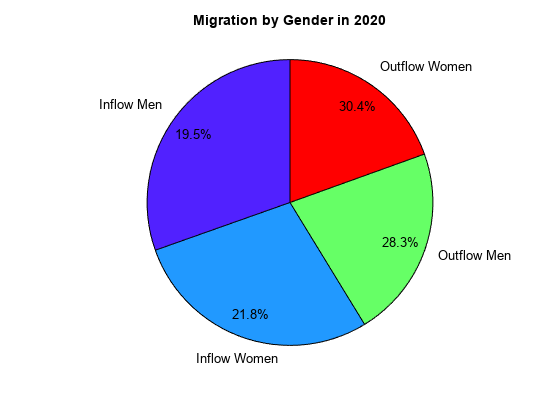




figure;
year = 2020;
pie([flyttingetetterrogkjnn_V1.InnflyttingerMenn(find(flyttingetetterrogkjnn_V1.VarName1 == string(year))), flyttingetetterrogkjnn_V1.InnflyttingerKvinner(find(flyttingetetterrogkjnn_V1.VarName1 == string(year))), flyttingetetterrogkjnn_V1.UtflyttingerMenn(find(flyttingetetterrogkjnn_V1.VarName1 == string(year))), flyttingetetterrogkjnn_V1.UtflyttingerKvinner(find(flyttingetetterrogkjnn_V1.VarName1 == string(year)))], {'Inflow Men', 'Inflow Women', 'Outflow Men', 'Outflow Women'});
colormap([0.32 0.13 1; 0.13 0.6 1; 0.4 1 0.4; 1 0 0]);
data = [flyttingetetterrogkjnn_V1.InnflyttingerMenn(find(flyttingetetterrogkjnn_V1.VarName1 == string(year))), flyttingetetterrogkjnn_V1.InnflyttingerKvinner(find(flyttingetetterrogkjnn_V1.VarName1 == string(year))), flyttingetetterrogkjnn_V1.UtflyttingerMenn(find(flyttingetetterrogkjnn_V1.VarName1 == string(year))), flyttingetetterrogkjnn_V1.UtflyttingerKvinner(find(flyttingetetterrogkjnn_V1.VarName1 == string(year)))];
% Calculate the percentages
percentages = data / sum(data) * 100;
pieText = findobj(gca, 'Type', 'text');
% Add the percentage labels
for i = 1:length(pieText)
    pos = get(pieText(i), 'Position') * 0.75;
    text(pos(1), pos(2), sprintf('%.1f%%', percentages(i)), 'Color', 'k', 'FontSize', 10, 'HorizontalAlignment', 'center', 'VerticalAlignment', 'middle');
end
title(('Migration by Gender in 2020'));

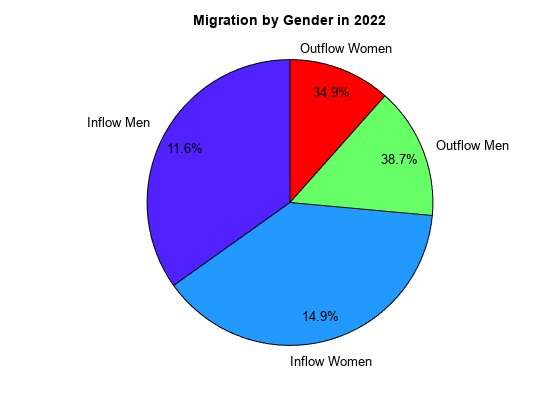


figure;
year = 2022;
pie([flyttingetetterrogkjnn_V1.InnflyttingerMenn(find(flyttingetetterrogkjnn_V1.VarName1 == string(year))), flyttingetetterrogkjnn_V1.InnflyttingerKvinner(find(flyttingetetterrogkjnn_V1.VarName1 == string(year))), flyttingetetterrogkjnn_V1.UtflyttingerMenn(find(flyttingetetterrogkjnn_V1.VarName1 == string(year))), flyttingetetterrogkjnn_V1.UtflyttingerKvinner(find(flyttingetetterrogkjnn_V1.VarName1 == string(year)))], {'Inflow Men', 'Inflow Women', 'Outflow Men', 'Outflow Women'});
colormap([0.32 0.13 1; 0.13 0.6 1; 0.4 1 0.4; 1 0 0]);
data = [flyttingetetterrogkjnn_V1.InnflyttingerMenn(find(flyttingetetterrogkjnn_V1.VarName1 == string(year))), flyttingetetterrogkjnn_V1.InnflyttingerKvinner(find(flyttingetetterrogkjnn_V1.VarName1 == string(year))), flyttingetetterrogkjnn_V1.UtflyttingerMenn(find(flyttingetetterrogkjnn_V1.VarName1 == string(year))), flyttingetetterrogkjnn_V1.UtflyttingerKvinner(find(flyttingetetterrogkjnn_V1.VarName1 == string(year)))];
% Calculate the percentages
percentages = data / sum(data) * 100;
pieText = findobj(gca, 'Type', 'text');
% Add the percentage labels
for i = 1:length(pieText)
    pos = get(pieText(i), 'Position') * 0.75;
    text(pos(1), pos(2), sprintf('%.1f%%', percentages(i)), 'Color', 'k', 'FontSize', 10, 'HorizontalAlignment', 'center', 'VerticalAlignment', 'middle');
end
title(('Migration by Gender in 2022'));

#### Part 4: ChatGPT (10%)

*This part of the assignment is in a sepparate file called ChatGPT - presentation*